# **DVB-S2 Simulation in a Tropical Channel**

clc, clearvars, close all;

## Simulation Parameters


chanParams = struct();
simParams = struct();

% waveform parameters
esno = 15;
numFrames = 3;
FECframe = 'normal';
MODCOD = 5;
RolloffFactor  = 0.35;
FilterSpanInSymbols = 10;
SPS = 2; % SamplesPerSymbol
HasPilots    = true;  %must be true !!
DFL       = getDFL(MODCOD,FECframe); %Data field length
filterDelay = FilterSpanInSymbols / 2;

% channel parameters
chanParams.Frequency_GHz    = 20; %frequency in ghz
chanParams.Latitude         = 5.17;
chanParams.Altitude_m       = 57;
chanParams.ElevationAngle   = 45;
chanParams.Polarization     = 'V'; %vertical polarization

% system parameters
simParams.G_s_dBi          = 52.0;
simParams.G_r_dBi          = 41.7;
simParams.NoiseBW_Hz       = 50e6;
simParams.NoiseTemp_K      = 207.0;
simParams.Theta3dB_deg     = 0.4;
simParams.BeamOffset_deg   = 0.0;

## Transmitter

% configuring the dvb-s2
wavegen = dvbs2WaveformGenerator;
wavegen.StreamFormat         = 'TS';
wavegen.NumInputStreams       = 1;
wavegen.FECFrame              = FECframe;
wavegen.MODCOD                = MODCOD;
wavegen.HasPilots             = HasPilots;
wavegen.RolloffFactor         = RolloffFactor;
wavegen.FilterSpanInSymbols   = FilterSpanInSymbols;
wavegen.SamplesPerSymbol      = SPS;
wavegen.DFL                   = DFL;


% input bits for the waveform
syncBits = [0;1;0;0;0;1;1;1];
pktLen   = 1496;

pn = comm.PNSequence('Polynomial','x9+x5+1', ...
    'InitialConditions',[zeros(1,8) 1], ...
    'VariableSizeOutput', true, ...
    'MaximumOutputSize', [64800 * numFrames, 1]);

numPkts   = wavegen.MinNumPackets(1) * numFrames;
reset(pn);
rawpkts   = pn(pktLen * numPkts);
txRawPkts = reshape(rawpkts, pktLen, numPkts);
txPkts    = [repmat(syncBits, 1, numPkts); txRawPkts];
inputBits = txPkts(:);

data = {inputBits};


% generate the waveform
txWaveform = [wavegen(data); flushFilter(wavegen)];



% Constellation Diagram
constel = comm.ConstellationDiagram(Title="Transmitted Data",...
    SamplesPerSymbol=wavegen.SamplesPerSymbol, ...
    ShowReferenceConstellation= false,...
    AxesLimits =[-1 1]);    

constel(txWaveform);
release(constel);

% filtering the TX for reference (used in BER calculation)
txFilt = comm.RaisedCosineReceiveFilter(...
    'RolloffFactor',         RolloffFactor, ...
    'FilterSpanInSymbols',   FilterSpanInSymbols, ...
    'InputSamplesPerSymbol', SPS, ...
    'DecimationFactor',      SPS);
txSym_raw = txFilt(txWaveform);
txSymbols     = txSym_raw(filterDelay+1:end);
release(txFilt);



% Get MODCOD physical layer parameters
[modOrder, codeRate, cwLen] = satcom.internal.dvbs.getS2PHYParams(...
    wavegen.MODCOD, wavegen.FECFrame);

dataLen    = cwLen / log2(modOrder);   % number of data symbols per PLFRAME
slotLen    = 90;                       % symbols per slot
pilotBlkFreq = 16;                     % pilot inserted every 16 data slots
pilotSymLen  = 36;                     % symbols per pilot block

% Number of pilot blocks (Eq. from DVB-S2 standard)
numPilotBlks = floor(dataLen / (slotLen * pilotBlkFreq));
if floor(dataLen/(slotLen*16)) == dataLen/(slotLen*pilotBlkFreq)
    numPilotBlks = numPilotBlks - 1;
end

pilotLen  = numPilotBlks * pilotSymLen;
plFrameSize = dataLen + pilotLen + slotLen;   % total PL frame symbols

fprintf(['           SUMMARY        \n', ...
         'MODCOD                  : %d\n', ...
         'Modulation Order        : %d\n', ...
         'Code Rate               : %.5f\n', ...
         'LDPC Codeword Length    : %d bits\n', ...
         'Data Symbols/Frame      : %d\n', ...
         'Pilot Blocks/Frame      : %d (%d symbols each)\n', ...
         'PL Frame Size           : %d symbols\n'], ...
         MODCOD, modOrder, codeRate, cwLen, dataLen, numPilotBlks, pilotSymLen, plFrameSize);

           SUMMARY        
MODCOD                  : 5
Modulation Order        : 4
Code Rate               : 0.60000
LDPC Codeword Length    : 64800 bits
Data Symbols/Frame      : 32400
Pilot Blocks/Frame      : 22 (36 symbols each)
PL Frame Size           : 33282 symbols



%  Build pilot indices and PL-scrambled reference pilots
%  (mirrors helper lines 143-146)
%
%  IMPORTANT: Pilots are PL-scrambled, NOT plain (1+j)/sqrt(2).
%  The PL scrambling sequence modifies each pilot symbol.
%  pilotInd gives positions within the XFECFRAME (before PLHEADER offset).
%  Final indices = pilotInd + slotLen  (skip PLHEADER = 90 symbols)

%  PL scrambling integer sequence (Gold code, root=0)
plScrambIntSeq = satcom.internal.dvbs.plScramblingIntegerSequence(0);
cMap  = [1; 1j; -1; -1j];
cSeq  = cMap(plScrambIntSeq + 1);   % complex scrambling sequence



% Pilot block positions within XFECFRAME
[~, pilotInd_raw] = satcom.internal.dvbs.pilotBlock(numPilotBlks);

% Add PLHEADER offset → positions within full PL frame
pilotInd  = pilotInd_raw + slotLen;   % slotLen = 90 = PLHEADER length

% PL-scrambled reference pilots: (1+j)/sqrt(2) * cSeq at pilot positions
refPilots = (1+1j)/sqrt(2) .* cSeq(pilotInd_raw);

fprintf('Pilot indices range : [%d, %d]\n', min(pilotInd), max(pilotInd));

Pilot indices range : [1531, 32562]


fprintf('refPilots (first 3) : %.3f+%.3fj  %.3f+%.3fj  %.3f+%.3fj\n',...
    real(refPilots(1)),imag(refPilots(1)),...
    real(refPilots(2)),imag(refPilots(2)),...
    real(refPilots(3)),imag(refPilots(3)));

refPilots (first 3) : 0.707+-0.707j  -0.707+-0.707j  -0.707+-0.707j


## Channel

%% specific rain attenuation
Ap_dB = 15;
Ap_linear = 10^(-Ap_dB/20);
phi = 2*pi*rand(1);

h_tilde = sqrt(Ap_linear)*exp(-1i*phi);
attWaveform = h_tilde*txWaveform;

snr = esno-10*log10(SPS);

fadedWaveform = awgn(attWaveform,snr,'measured');
% only awgn noise
%noisyWaveform = awgn(txWaveform, snr);

## Receiver


rxWaveform = fadedWaveform;
% Constellation Diagram
constel = comm.ConstellationDiagram(Title="Received Data",...
    SamplesPerSymbol=1, ...
    ShowReferenceConstellation= false,...
    AxesLimits =[-1 1]);    
rxFilter = comm.RaisedCosineReceiveFilter( ...
    'RolloffFactor',         wavegen.RolloffFactor, ...
    'FilterSpanInSymbols',   wavegen.FilterSpanInSymbols, ...
    'InputSamplesPerSymbol', wavegen.SamplesPerSymbol, ...
    'DecimationFactor',      wavegen.SamplesPerSymbol);

rxSym_raw   = rxFilter(rxWaveform);
filterDelay = wavegen.FilterSpanInSymbols;
rxSymbols   = rxSym_raw(filterDelay+1:end);
release(rxFilter);

constel(rxSymbols);
release(constel);


for stIdx = 1: numFrames
    % Extract one PL frame
    endIdx = stIdx + plFrameSize*SPS;

    isLastFrame = endIdx>length(rxWaveform);
    
    if ~isLastFrame

        if length(rxSymbols) >= plFrameSize
            rxFrame = rxSymbols(1:plFrameSize);
            txFrame = txSymbols(1:plFrameSize);
        else
            rxFrame = rxSymbols;
            txFrame = txSymybols(1:length(rxSymbols));
            warning('Fewer symbols than expected PL frame size.');
        end
        fprintf('Symbols in RX frame : %d\n', length(rxFrame));

## LS Estimator

        pilotBlock = rxFrame(pilotInd);
        LS_est = pilotBlock./refPilots;
        LS_matrix = reshape(LS_est, pilotSymLen, numPilotBlks);
        
        LS_mean_blk = mean(LS_matrix,1);
        H_ls = mean(LS_mean_blk)

## Received Signal Recovery

Symbols in RX frame : 33282


H_ls = -0.2912 + 0.0513i

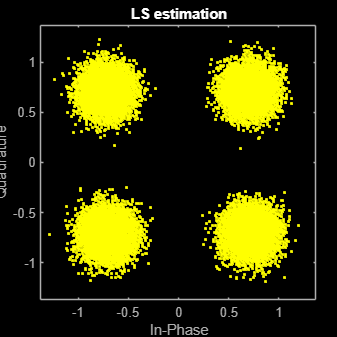

PL Header successfully decoded


        ModulationOrder: 4
         FECFrameLength: 64800
     LDPCCodeIdentifier: "3/5"
         PLSDecimalCode: 21
      TimeSlicingNumber: -1
    CanonicalMODCODName: ""
              HasPilots: 1
           IsDummyFrame: 0



nVar = 0.0323

Total Bits Compared : 37600


Total Bit Errors    : 0


Bit Error Rate (BER): 0


Symbols in RX frame : 33282


H_ls = -0.2912 + 0.0513i

PL Header successfully decoded


        ModulationOrder: 4
         FECFrameLength: 64800
     LDPCCodeIdentifier: "3/5"
         PLSDecimalCode: 21
      TimeSlicingNumber: -1
    CanonicalMODCODName: ""
              HasPilots: 1
           IsDummyFrame: 0



nVar = 0.0323

Total Bits Compared : 37600


Total Bit Errors    : 0


Bit Error Rate (BER): 0


Symbols in RX frame : 33282


H_ls = -0.2912 + 0.0513i

PL Header successfully decoded


        ModulationOrder: 4
         FECFrameLength: 64800
     LDPCCodeIdentifier: "3/5"
         PLSDecimalCode: 21
      TimeSlicingNumber: -1
    CanonicalMODCODName: ""
              HasPilots: 1
           IsDummyFrame: 0



nVar = 0.0323

Total Bits Compared : 37600


Total Bit Errors    : 0


Bit Error Rate (BER): 0


        % PL header recovery
        rxFrame = rxFrame./H_ls;
        
        % visualization after equalization
        scatterplot(rxFrame);
        title("LS estimation");
        
        rxPLHeader = rxFrame(1:90);
        
        
        phyParams = dvbsPLHeaderRecover(rxPLHeader,Mode="DVB-S2/S2X regular");
        M = phyParams.ModulationOrder;
        if M == 0
            R = [];
        else
            R = eval(phyParams.LDPCCodeIdentifier);
        end
        fecFrame = phyParams.FECFrameLength;
        pilotStat = phyParams.HasPilots;
        xFECFrameLen = fecFrame/log2(M);
        % Validate the decoded PL header.
        if M ~= modOrder || R ~= codeRate || ...
                fecFrame ~= cwLen || ~pilotStat
            fprintf("%s\n","PL header decoding failed");
            isHeaderRecovered  = false;
        else
            fprintf("PL Header successfully decoded\n");
            disp(phyParams);
            isHeaderRecovered  = true;
        end
        % demodulation and decoding
        
        %estimating the noise varience
        nVar = DVBS2NoiseVarEstimate(rxFrame,pilotInd,refPilots,false)
         % dvbs2BitRecover function
        [decBitsTemp, isFrameLost]  = dvbs2BitRecover(rxFrame,nVar,false);
        recoveredBits = decBitsTemp;
        
        % 1. Extract the bits from the cell array
        originalBits = data; 
        
        % 2. Ensure both arrays are column vectors
        originalBits = vertcat(originalBits{:});
        originalBits = originalBits(:); % Just to be absolutely safe
        
        recoveredBits = vertcat(recoveredBits{:});
        recoveredBits = recoveredBits(:);
        
        
        
        
        % 2. Check if the receiver actually recovered anything!
        if isempty(recoveredBits) || isempty(originalBits)
            if isHeaderRecovered
                fprintf("The Header recoverd but output bit 0");
            else
                fprintf(' WARNING: Frame completely lost or header corrupted. Receiver output 0 bits.\n');
            end
            
            % Since the entire frame was dropped, we count all bits as errors
            numErrors = length(originalBits); 
            totalBits = length(originalBits);
            ber = 1.0; % 100% error for this frame
            
            fprintf('Total Bits Compared : %d\n', totalBits);
            fprintf('Total Bit Errors    : %d (Dropped Frame)\n', numErrors);
            
        else
            % 3. Safe to compute BER
            minLen = min(length(originalBits), length(recoveredBits));
            origAligned = originalBits(1:minLen);
            recAligned = recoveredBits(1:minLen);
            
            [numErrors, ber] = biterr(origAligned, recAligned);
            totalBits = minLen;
            
            fprintf('Total Bits Compared : %d\n', totalBits);
            fprintf('Total Bit Errors    : %d\n', numErrors);
            
            % Print BER cleanly
            if ber == 0
                fprintf('Bit Error Rate (BER): 0\n');
            else
                fprintf('Bit Error Rate (BER): %.2f x 10^%d\n', ...
                    ber / (10^floor(log10(ber))), floor(log10(ber)));
            end
        end
    else
        break;
    end
end

## Spectrum Analyzer

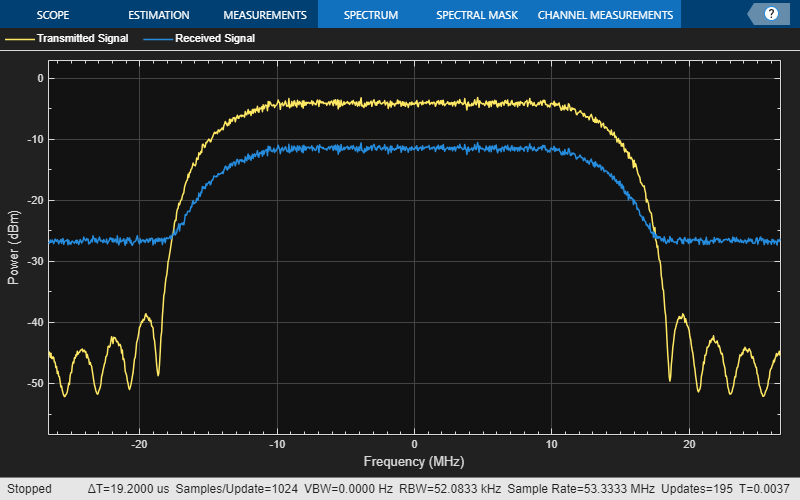

BW = 36e6; % typical satellite transponder bandwidth
symbolRate = BW/(1+wavegen.RolloffFactor);
Fs = symbolRate*wavegen.SamplesPerSymbol;

spectrum = spectrumAnalyzer( SampleRate= Fs,AveragingMethod="exponential" ,ForgettingFactor = 1,...
                           ChannelNames=["Transmitted Signal", "Received Signal"], ShowLegend=true);

spectrum([txWaveform, rxWaveform]);
release(spectrum);

## Helper Function

function dfl = getDFL(modCod,fecFrame)
% Get data field length
    if strcmp(fecFrame,"normal")
        nDefVal = [16008 21408 25728 32208 38688 43040 48408 51648 53840 57472 ...
            58192 38688 43040 48408 53840 57472 58192 43040 48408 51648 53840 ...
            57472 58192 48408 51648 53840 57472 58192] - 80;
    else
        % MODCOD values 11, 17, 23, and 28 are not valid when you set the FECFrame property to "short"
        nDefVal = [3072 5232 6312 7032 9552 10632 11712 12432 13152 14232 0 ...
            9552 10632 11712 13152 14232 0 10632 11712 12432 13152 14232 0 11712 ...
            12432 13152 14232 0] - 80;
    end
    dfl = nDefVal(modCod);
end

function nVarEst = DVBS2NoiseVarEstimate(rxData, pilotInd, refPilots, normFlag)
  
    %   NVAREST = HelperDVBS2NoiseVarEstimate(RXDATA, PILOTIND, REFPILOTS, ...
    %   NORMFLAG) estimates noise variance on the pilot symbols present in
    %   received PL frame, RXDATA, using the pilot indices, PILOTIND, PL
    %   scrambled reference pilots, REFPILOTS. The soft bits are calculated on
    %   unit average power constellation in demodulator. The noise variance
    %   estimate must be calculated w.r.t unit average scaled constellation. If
    %   constellation normalization flag is set as false, the received PL frame
    %   constellation will be normalized and noise variance will be estimated.
    %   Data-aided maximum likelihood estimator (SNORE) is used.
    
    
    if normFlag
        rxData = rxData/sqrt(mean(abs(rxData).^2));
    end
    rxPilots = rxData(pilotInd, :);
    pSigN = mean(abs(rxPilots).^2);
    % If received pilots and reference pilots are at the same amplitude
    % scaling, abs() is enough to compute the signal power. If they are at different
    % scaling levels, abs()^2 gives the appropriate scaling factor in the power
    % calculation equation.
    % mean((A+N)/K.*(A+N)/K) = A^2/K^2
    % abs(mean((A+N)/K.*A)) = A^2/K
    % abs(mean((A+N)/K.*A))^2 = A^4/K^2   A must be unit average scaled. 
    pSig = abs(mean(rxPilots.*conj(refPilots))).^2;
    nVarEst = abs(mean(pSigN-pSig));

end